%%Parameters
F = 0;
G = 1/(50^(1/2));
N = 50;
Ks = 1;
neta = 1;
f1 = 1;
p0 = .5;

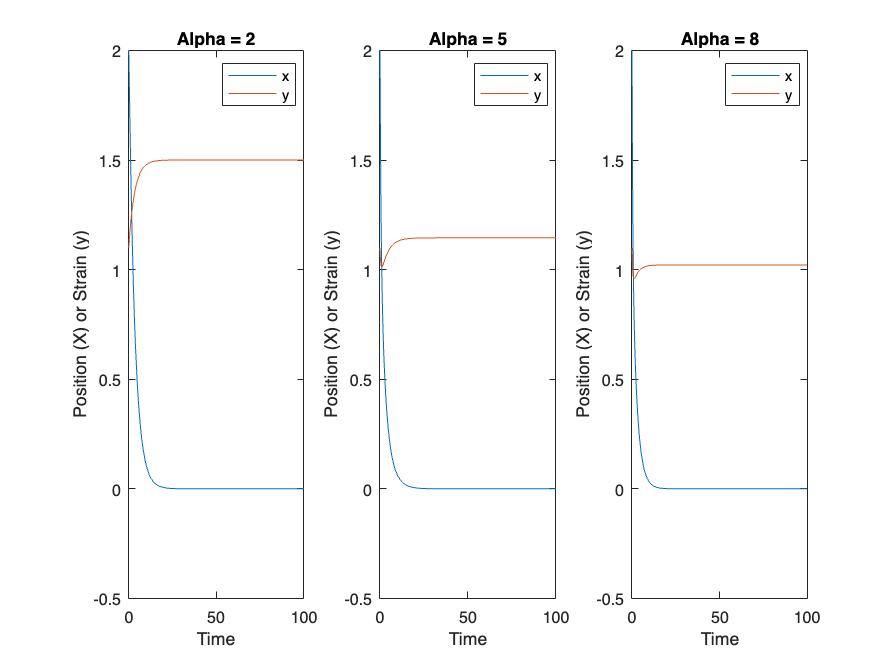

%% Solution - Case 1.
C=0; 
al = [2 5 8];

% equation.
C = 0;
al_arr = [2 5 8];
figure;
for i = 1:length(al_arr)
    
    al = al_arr(i);
    % other constants.
    y0 = f1*(1-C*p0) + p0;
    Xs = ((N * G)/Ks) * (y0-p0);
    A = (1-p0)/p0*exp(al*y0);
    % solve equation.
    dy = @(t,y)[F-Ks*(y(1)-Xs)-(N*G)*(y(2)-(1/(1+A*exp(-al*y(2)))));...
        (f1*neta) + G*(F-Ks*(y(1)-Xs)) - y(2)*(N*G^2 + neta) + ...
        (1/(1+A*exp(-al*y(2))))*(N*G^2 + neta*(1-C*f1))];
    
    [T, Y] = ode15s(dy,[0 100],[2 1.1]);
    
    % plot X and y against time.
    subplot(1,length(al_arr),i)
    plot(T, Y(1:end,1))
    hold on;
 
    plot(T, Y(1:end,2))
    xlabel('Time')
    ylabel('Position (X) or Strain (y)')
    legend ('x', 'y')
    title(['Alpha = ', num2str(al)]);
end

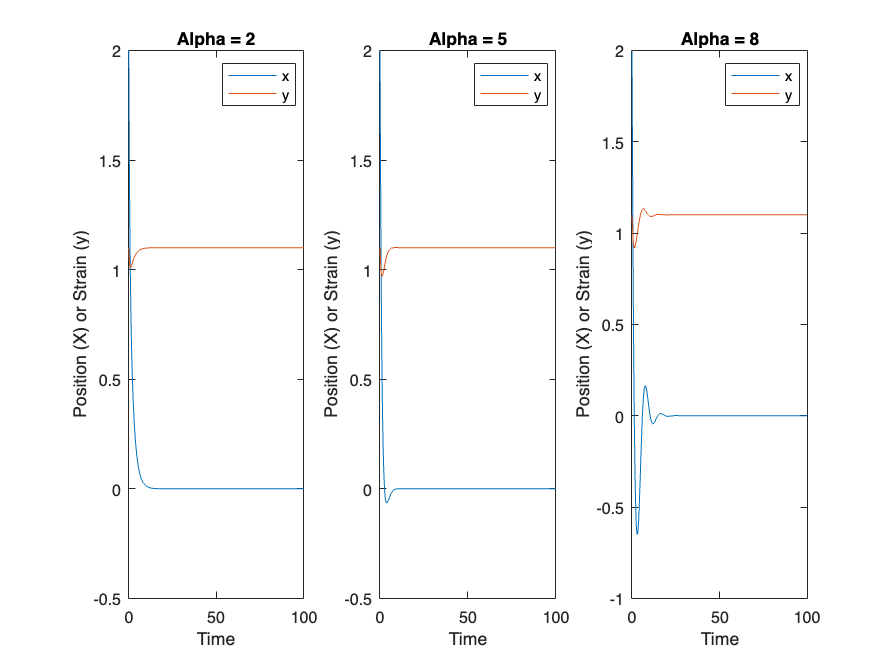

%% Solution - Case 2.
C = 0.8; 
al = [8 15 25];

% equation.
figure;
for i = 1:length(al_arr)
    
    al = al_arr(i);
    % other constants.
    y0 = f1*(1-C*p0) + p0;
    Xs = ((N * G)/Ks) * (y0-p0);
    A = (1-p0)/p0*exp(al*y0);
    % solve equation.
    dy = @(t,y)[F-Ks*(y(1)-Xs)-(N*G)*(y(2)-(1/(1+A*exp(-al*y(2)))));...
        (f1*neta) + G*(F-Ks*(y(1)-Xs)) - y(2)*(N*G^2 + neta) + ...
        (1/(1+A*exp(-al*y(2))))*(N*G^2 + neta*(1-C*f1))];
    
    [T, Y] = ode15s(dy,[0 100],[2 1.1]);
    
    % plot X and y against time.
    subplot(1,length(al_arr),i)
    plot(T, Y(1:end,1))
    hold on;
 
    plot(T, Y(1:end,2))
    xlabel('Time')
    ylabel('Position (X) or Strain (y)')
    legend ('x', 'y')
    title(['Alpha = ', num2str(al)]);
end

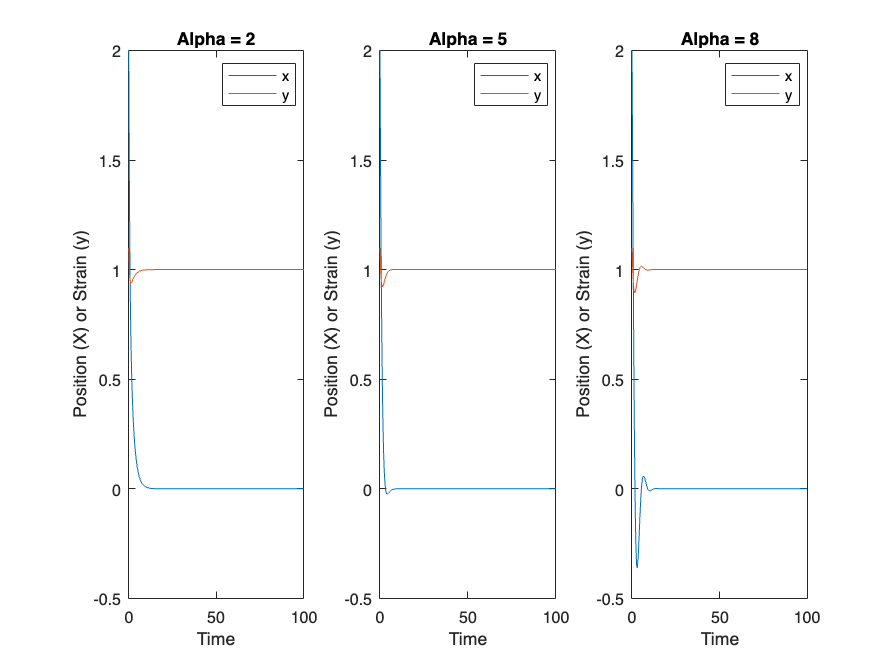

%% Solution - Case 3.
C = 1; 
al = [10 15 25];

% equation.
figure;
for i = 1:length(al_arr)
    
    al = al_arr(i);
    % other constants.
    y0 = f1*(1-C*p0) + p0;
    Xs = ((N * G)/Ks) * (y0-p0);
    A = (1-p0)/p0*exp(al*y0);
    % solve equation.
    dy = @(t,y)[F-Ks*(y(1)-Xs)-(N*G)*(y(2)-(1/(1+A*exp(-al*y(2)))));...
        (f1*neta) + G*(F-Ks*(y(1)-Xs)) - y(2)*(N*G^2 + neta) + ...
        (1/(1+A*exp(-al*y(2))))*(N*G^2 + neta*(1-C*f1))];
    
    [T, Y] = ode15s(dy,[0 100],[2 1.1]);
    
    % plot X and y against time.
    subplot(1,length(al_arr),i)
    plot(T, Y(1:end,1))
    hold on;
 
    plot(T, Y(1:end,2))
    xlabel('Time')
    ylabel('Position (X) or Strain (y)')
    legend ('x', 'y')
    title(['Alpha = ', num2str(al)]);
end